**EE 150**

**Signals and Systems**

** Lab 5 Sampling and Reconstruction**

Date Performed: 2022.11.24

Class Id: Thur_105

Name & ID: 王鹏豪_2021533138_周守琛_2021533042

1.1 Analyze signal1. Plot the original signal and its spectrum (amp-freq).

1.2 Sample signal1 at 1.5 times of its maximum frequency and then reconstruct it. Plot the sampled signal, the spectrum of the sampled signal and the reconstructed signal.

1.3  Sample signal1 at 3 times of its maximum frequency and then reconstruct it. Plot the sampled signal, the spectrum of the sampled signal and the reconstructed signal.


$$\mathrm{signal}1=\sin \left(6\pi t\right)+0\ldotp 5*\cos \left(4\ldotp 8\pi t\right)$$


Make a  3*3 plot as following.

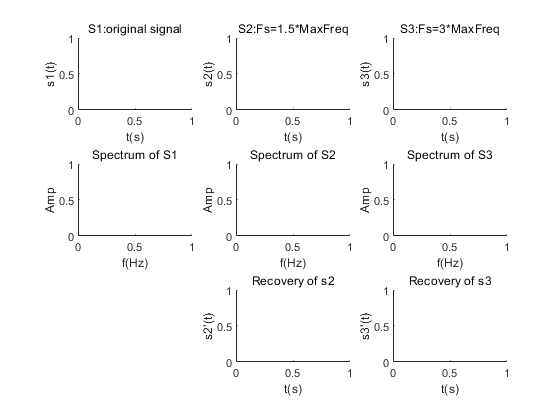

clear;clf;

dt = 0.01;
t = 0:dt:5;
signal1 = sin(6*pi.*t) + 0.5*cos(4.8*pi.*t);
Fs = 1/dt;
ds = 1/Fs;
sample_interval = floor(ds/dt);
f_sample = signal1(1:sample_interval:end);
t_sample = t(1:sample_interval:end);
Ts = sample_interval*dt;
sigLen = length(f_sample);
N = sigLen;

subplot(3,3,1);
plot(t,signal1);
title("S1:origin signal");
xlabel("t(s)");
ylabel("s1(t)");
xlim([0,5]);

X = fft(signal1);
X_shift = fftshift(X);
df = Fs/N;
f = (-N/2:N/2-1)*df;
subplot(3,3,4);
plot(f,abs(X_shift)/N);
xlim([-5,5]);
title("Spectrum of S1");
xlabel("f(Hz)");
ylabel("Amp");

signal1 = sin(6*pi*t) + 0.5*cos(4.8*pi*t)

            = sin(2*pi*freq1*t) + 0.5*cos(2*pi*freq2*t)

so freq1 = 3, freq2 = 2.4

max_freq = max(freq1,freq2) =3

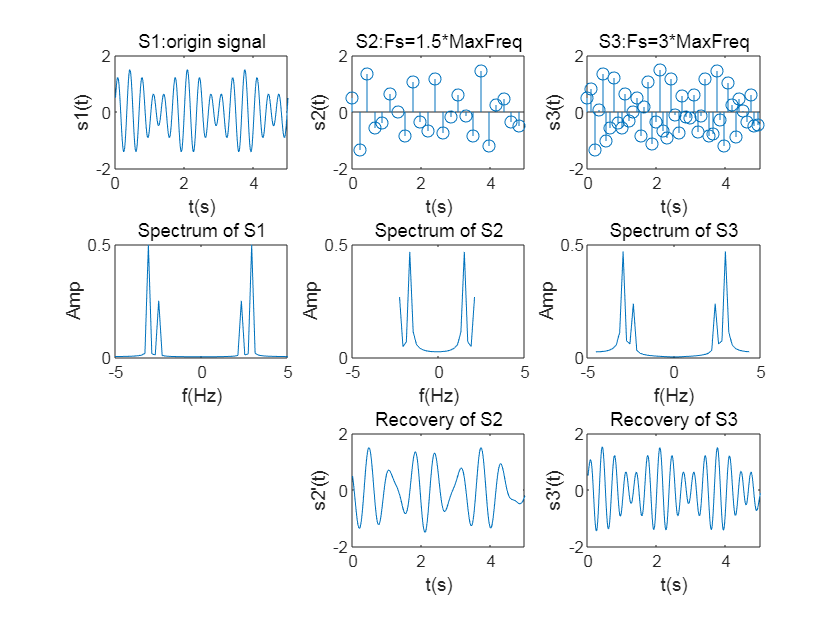

%--------------------------------------------
freq = 3;
Fs = 1.5*freq;
ds = 1/Fs;
sample_interval = floor(ds/dt);
f_sample = signal1(1:sample_interval:end);
t_sample = t(1:sample_interval:end);
Ts = sample_interval*dt;
sigLen = length(f_sample);
N = sigLen;
subplot(3,3,2);
stem(t_sample,f_sample);
xlabel("t(s)");
xlim([0,5]);
ylabel("s2(t)");
title("S2:Fs=1.5*MaxFreq");

Fs = 1/Ts; df = Fs/N;
F = fftshift(fft(f_sample))/sigLen;
f = (-N/2:N/2-1)*df;
subplot(3,3,5);
plot(f,abs(F));
xlabel("f(Hz)");
xlim([-5,5]);
ylabel("Amp");
title("Spectrum of S2");

subplot(3,3,8);
x_recon=zeros(length(t),1);
for k=1:length(t)
 for n=1:length(f_sample)
 x_recon(k) = x_recon(k) + f_sample(n)*sinc(((k-1)*dt-(n-1)*Ts)/(Ts));
 end
 plot(t,x_recon);
end
xlabel("t(s)");
xlim([0,5]);
ylabel("s2'(t)");
title("Recovery of S2");

%--------------------------------------------

freq = 3;
Fs = 3*freq;
ds = 1/Fs;
sample_interval = floor(ds/dt);
f_sample = signal1(1:sample_interval:end);
t_sample = t(1:sample_interval:end);
Ts = sample_interval*dt;
sigLen = length(f_sample);
N = sigLen;

subplot(3,3,3);
stem(t_sample,f_sample);
xlabel("t(s)");
xlim([0,5]);
ylabel("s3(t)");
title("S3:Fs=3*MaxFreq");


Fs = 1/Ts; df = Fs/N;
F = fftshift(fft(f_sample))/sigLen;
f = (-N/2:N/2-1)*df;
subplot(3,3,6);
plot(f,abs(F));
xlabel("f(Hz)");
xlim([-5,5]);
ylabel("Amp");
title("Spectrum of S3");

subplot(3,3,9);
x_recon=zeros(length(t),1);
for k=1:length(t)
 for n=1:length(f_sample)
 x_recon(k) = x_recon(k) + f_sample(n)*sinc(((k-1)*dt-(n-1)*Ts)/(Ts));
 end
 plot(t,x_recon);
end
xlabel("t(s)");
xlim([0,5]);
ylabel("s3'(t)");
title("Recovery of S3");

2 Load ***Lab5_music.mat***. It's a piece of music downed in noise. 

2.1 Plot the original signal in both time domain and frequency domain (amplitude-frequency only) in a 1*2 subplot.

2.2 Observe the spectrum of the original signal to find out the signal bandwidth **fb**. Take 2***fb** as the sampling frequency, then sample the original signal. Plot the the sampled signal in both time domain and frequency domain in a 1*2 subplot. Play and listen to it.

2.3  Use an appropriate anti-aliasing filter to filter the original signal. Plot the filtered signal in both time domain and frequency domain in a 1*2 subplot.

2.4  Take 2***fb** as the sampling frequency, sample the filtered signal, then draw the sampled signal in both time domain and frequency domain in a 1*2 subplot. Play and listen to it.

Tips:

Load ***Lab5_music.mat*** with function **Load(Lab5_music.mat** **) **to get the original signal. 

Use** figure** to create a new canva for each 6.x.

clear;clf;

2.1

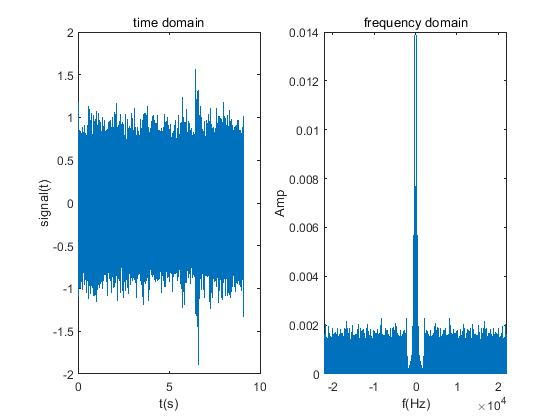

load("MATLAB\Lab5_music.mat");

figure(1);
subplot(1,2,1);
dt = 1/Fs;
t = (0:dt:length(signal)/Fs-dt);
plot(t,signal');
xlabel("t(s)");
ylabel("signal(t)");
title("time domain");

subplot(1,2,2);
X = fft(signal);
N = length(X);
df = Fs / N;
f = (-N/2:N/2-1)*df;
X_shift = fftshift(X)/N;
plot(f,abs(X_shift));
xlabel("f(Hz)");
ylabel("Amp");
title("frequency domain");

2.2

check the amplitude-frequency plot, we can discover the bandwidth **fb = 1500**

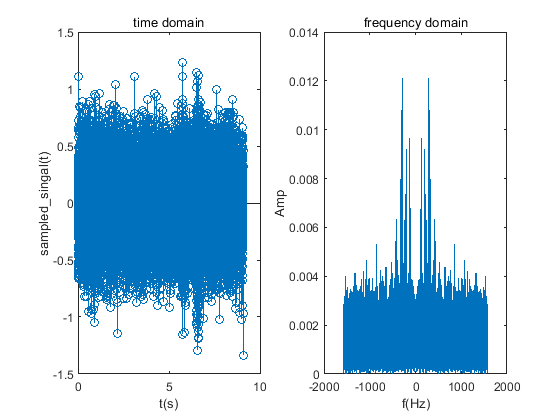

figure(2);
fb = 1500;

%sound(signal,Fs);

fs = 2*fb; % sampling frequency

ds = 1/fs;
sample_interval = floor(ds/dt);
f_sample = signal(1:sample_interval:end);
t_sample = t(1:sample_interval:end);

%sound(f_sample,Fs);

Ts = sample_interval*dt;
sigLen = length(f_sample);
N = sigLen;
subplot(1,2,1);
stem(t_sample,f_sample);
xlabel("t(s)");
ylabel("sampled\_singal(t)");
title("time domain");

fs = 1/Ts; df = fs/N;
F = fftshift(fft(f_sample))/sigLen;
f = (-N/2:N/2-1)*df;
subplot(1,2,2);
plot(f,abs(F));
xlabel("f(Hz)");
%xlim([-5,5]);
ylabel("Amp");
title("frequency domain");

sound(f_sample,fs);
pause(10);

2.3

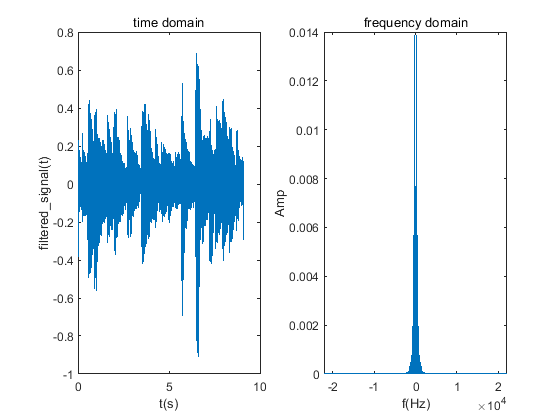

fc = fb;
[b,a] = butter(8,fc/(Fs/2));
% [H w] = freqz(b,a);

filter_signal = filter(b,a,signal);

figure(3);
subplot(1,2,1);
dt = 1/Fs;
t = (0:dt:length(signal)/Fs-dt);
plot(t,filter_signal);
xlabel("t(s)");
ylabel("filtered\_signal(t)");
title("time domain");

subplot(1,2,2);
X = fft(filter_signal);
N = length(X);
df = Fs / N;
f = (-N/2:N/2-1)*df;
X_shift = fftshift(X)/N;
plot(f,abs(X_shift));
xlabel("f(Hz)");
ylabel("Amp");
title("frequency domain");

2.4

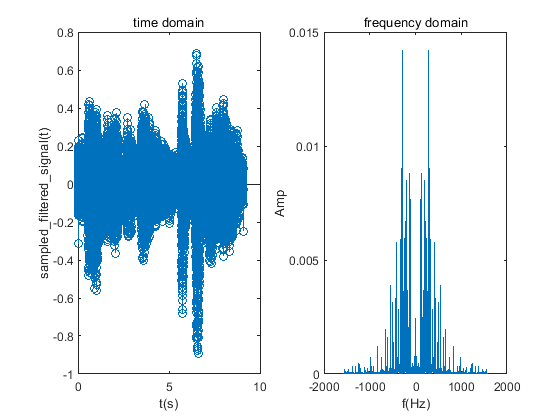

figure(4);

fs = 2*fb;
ds = 1/fs;
sample_interval = floor(ds/dt);
f_sample = filter_signal(1:sample_interval:end);
t_sample = t(1:sample_interval:end);

Ts = sample_interval*dt;
sigLen = length(f_sample);
N = sigLen;
subplot(1,2,1);
stem(t_sample,f_sample);
xlabel("t(s)");
ylabel("sampled\_filtered\_signal(t)");
title("time domain");

fs = 1/Ts; df = fs/N;
F = fftshift(fft(f_sample))/sigLen;
f = (-N/2:N/2-1)*df;
subplot(1,2,2);
plot(f,abs(F));
xlabel("f(Hz)");
%xlim([-5,5]);
ylabel("Amp");
title("frequency domain");

subplot(1,2,2);

sound(f_sample,fs);
pause(10);